# **Interpolação**

**Exercício 1:** Encontre o polinômio de grau <= 2 que interpola os pontos (-1,4),(0,1), (2,-1).

Implementação do sistema a ser resolvido:

%Encontra o polinômio interpolador por resolução do sistema 
%Encontra o polinômio interpolador por resolução do sistema 
x = [ -1; 0; 2];
y = [4; 1; -1];

%1 -  Criação da matriz de Vandermonde A
n = length(x);
k = 2;  %grau do polinômio
for i = 1:n
    for j = 1:k+1
        A(i,j) = x(i)^(j-1);
    end
end
%Resolução do sistema A*a = y, a = [a0, a1, a2]
a = A\y;
p2 = a(1)+a(2)*(-0.5)+a(3)*(0.5).^2 %polinômio interpolador


Graficamente,

x1 = linspace(-1,2);%criação de um vetor de pontos linearmente espaçados num intervalo de [-1,2]
p2 = a(1)+a(2)*x1+a(3)*x1.^2;%polinômio interpolador
figure
plot(x,y,'o')
hold on
plot(x1,p2)
hold off

Função POLYFIT:

%Utilizar a função do MatLab polyfit p = [a2,a1,a0]
p = polyfit(x,y,2);
polyval(p,-0.5) % avalia o polinômio interpolado no ponto desejado


**Polinômio de Lagrange**


$$p_{n}(x) = \displaystyle \sum_{k=0}^{n} y_{k}L_{k}(x)$$



$$L_{k}(x) = \displaystyle \frac{\prod_{j=0,j\neq k}^{n} (x-x_{j})}{ \prod_{j=0,j\neq k}^{n}(x_{k}-x_{j})}$$


Implementação da forma de Lagrange:

%Encontra o polinômio interpolador usando a forma de Lagrange
x = [ -1 0 2];
y = [4 1 -1];
n = length(x);
m = 2;
syms X
s=0;
for k = 1:(m+1)
    prod1=1;
    prod2=1;

    for j = 1:n
        if j ~= k
            prod1 = prod1*(X - x(j));
            prod2 = prod2*(x(k) - x(j));
        end
        
    end
    L(k) = prod1/prod2;
    s = s + L(k)*y(k);
end
p=s

**Exercício 2: **Os dados a seguir definem a concentração no nível do mar do oxigênio dissolvido em água fresca como função da temperatura 

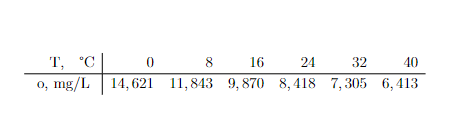

Obtenha estimativas de $o(27)$ usando 

a) Interpolação linear

%x0 = 24 e x1 = 32  pois 27°C pertence a esse intervalo
x = [24 32];
y = [8.418 7.305];
p = polyfit(x,y,1); % p= 11.7570*x - 0.1391
o27 = polyval(p,27)

b) Polinômio interpolador de Lagrange de grau $n\leq 5$.

clear
x = [ 0 8 16 24 32 40];
y = [14.621 11.843 9.870 8.418 7.305 6.413];
n = length(x);
m = 5; %grau do polinômio
X =27;
s=0;
for k = 1:(m+1)
    prod1=1;
    prod2=1;

    for j = 1:n
        if j ~= k
            prod1 = prod1*(X - x(j));
            prod2 = prod2*(x(k) - x(j));
        end
        
    end
    L(k) = prod1/prod2;
    s = s + L(k)*y(k);
end
p=s


**Exercício 3: **Gere oito pontos igualmente espaçados para a função $f(t)=\sin^{2}{t}$ de $t=0$ a $2\pi$. Ajuste esses dadoa com um polinômio interpolador de ordem 7.

a = 0;
b = 2*pi;
h = (b-a)/7;
t = [0 h 2*h 3*h 4*h 5*h 6*h 7*h];
ft =  (sin(t)).^2;
p = polyfit(t,ft,7);
p0 = polyval(p,0);
x1 = linspace(0,2*pi);%criação de um vetor de pontos linearmente espaçados num intervalo de [-1,2]
a = polyfit(t,ft,7);
p2 = a(8)+a(7)*x1+a(6)*x1.^2+a(5)*x1.^3+a(4)*x1.^4+a(3)*x1.^5+a(2)*x1.^6+a(1)*x1.^7;%polinômio interpolador
figure
plot(t,ft,'o')
hold on
plot(x1,p2)
hold off

Com base no ex 3

syms f(x)
f(x) = (sin(x))^2;
df8 = diff(f(x),x,8)

h = (2*pi-0)/7;
E7 = (h^(8) * 12)/4*8